# KF tuning with Grid Search Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers\n', p.NumWorkers);

Using 8 parallel workers


## Generate log grid

N_points    = 50;
lower_bound = -10;
upper_bound = 2;
qi_vec = logspace(lower_bound, upper_bound, N_points);
qF_vec = logspace(lower_bound, upper_bound, N_points);
[QI_MAT, QF_MAT] = meshgrid(qi_vec, qF_vec);
qi_flat = QI_MAT(:);
qF_flat = QF_MAT(:);
total_sims = numel(qi_flat);

## Objective function

function cost = objective_function(x)
    try
        cost = KF_simulate(x);
    catch
        cost = 0.01;
    end
end
run_sim = @(q_i, q_f) objective_function(table(q_i, q_f, 'VariableNames', {'qi', 'qF'}));

## Grid Search Optimization

cost_results = zeros(total_sims, 1);

tic
parfor i = 1:total_sims
    val_qi = qi_flat(i);
    val_qF = qF_flat(i);
    cost_results(i) = run_sim(val_qi, val_qF); 
end
toc

Elapsed time is 368.253404 seconds.


## Prepare data

X = table(qi_flat, qF_flat, 'VariableNames', {'qi', 'qF'});
Y = cost_results;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :);
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

sorted_Trace = 2500×3 table
       qi           qF           Cost   
    ________    __________    __________

         100     0.0012649    9.2396e-05
      56.899    0.00071969    9.2396e-05
      32.375    0.00040949    9.2396e-05
      18.421      0.000233    9.2396e-05
      10.481    0.00013257    9.2396e-05
      5.9636    7.5431e-05    9.2396e-05
      3.3932    4.2919e-05    9.2396e-05
      1.9307    2.4421e-05    9.2396e-05
      1.0985    1.3895e-05    9.2397e-05
     0.62506     7.906e-06    9.2397e-05
     0.35565    4.4984e-06    9.2399e-05
     0.20236    2.5595e-06    9.2401e-05
     0.11514    1.4563e-06    9.2408e-05
    0.065513    8.2864e-07    9.2424e-05
    0.037276    4.7149e-07    9.2466e-05
     0.02121    2.6827e-07     9.258e-05


## Plot results

COST_MAT = reshape(cost_results, size(QI_MAT));
min_cost = Y(1);
best_qi = X.qi(1);
best_qF = X.qF(1);

figure('Name', 'Grid Search Optimization Results', 'Color', 'w', 'Position', [100, 100, 900, 700]);
hold on;

Interpolated surface

surf_h = surf(QI_MAT, QF_MAT, COST_MAT, ...
    'EdgeColor', 'none', ...
    'FaceColor', 'interp', ...
    'FaceAlpha', 0.7);







hold on; 

% 1. Definir cuántas líneas de nivel quieres
n_niveles = 20; 

% 2. Dibujar los contornos en 3D (sobre la superficie)
% 'k' hace que las líneas sean negras para contrastar con el mapa de color 'jet'
[~, h_cont] = contour3(QI_MAT, QF_MAT, COST_MAT, n_niveles, 'k');

% 3. Ajustar estética de las líneas
h_cont.LineWidth = 1.2;






ratios_to_plot = [0.001, 10, 1000]; 

% Pequeño offset en Z para que la línea no quede "enterrada" en la superficie
z_lift = (max(cost_results) - min(cost_results)) * 0.02; 

for r = ratios_to_plot
    % 1. Generar coordenadas X (qi) densas para que la línea se vea suave
    line_qi = logspace(log10(min(qi_flat)), log10(max(qi_flat)), 100);
    
    % 2. Calcular coordenadas Y (qF) basadas en la relación: qi / qF = r -> qF = qi / r
    line_qF = line_qi / r;
    
    % 3. Filtrar puntos que caen fuera de tu rango de simulación
    valid_mask = (line_qF >= min(qF_flat)) & (line_qF <= max(qF_flat));
    line_qi = line_qi(valid_mask);
    line_qF = line_qF(valid_mask);
    
    if ~isempty(line_qi)
        % 4. Interpolación Mágica: Calcular la altura (Costo) en esos puntos exactos
        % Usamos interp2 sobre tus matrices originales
        line_cost = interp2(QI_MAT, QF_MAT, COST_MAT, line_qi, line_qF, 'linear');
        
        % 5. Graficar la línea sobre la superficie (blanca punteada)
        plot3(line_qi, line_qF, line_cost + z_lift, ...
              'w--', 'LineWidth', 1.5, 'DisplayName', sprintf('Ratio %.2g', r));
          
        % 6. (Opcional) Agregar etiqueta de texto al final de la línea
        text(line_qi(end), line_qF(end), line_cost(end) + z_lift, ...
             sprintf('  R=%.2g', r), ...
             'Color', 'k', 'BackgroundColor', 'w', 'FontSize', 8, 'Margin', 1);
    end
end





Grid points

scatter_h = scatter3(qi_flat, qF_flat, cost_results, ...
    1, 'k', 'filled', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceAlpha', 0.5);

Minimum value

min_h = plot3(best_qi, best_qF, min_cost, ...
    'rp', 'MarkerSize', 22, ...
    'MarkerFaceColor', 'r', ...
    'LineWidth', 2);

Format

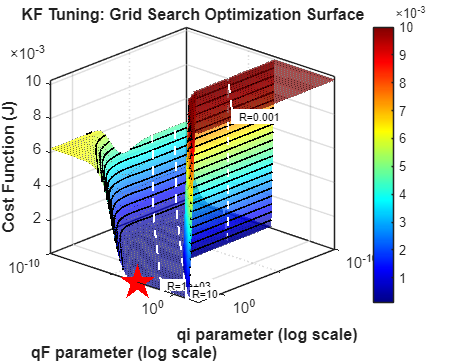

set(gca, 'XScale', 'log', 'YScale', 'log', 'FontSize', 11);

xlabel('qi parameter (log scale)', 'FontWeight', 'bold');
ylabel('qF parameter (log scale)', 'FontWeight', 'bold');
zlabel('Cost Function (J)', 'FontWeight', 'bold');
title('KF Tuning: Grid Search Optimization Surface', 'FontSize', 12);

colorbar;
colormap(jet);
view(135, 30);
grid on; box on;